1. Загрузите набор данных **ex1data1.txt** из текстового файла.

data = load('ex1data1.txt');
X = data(:, 1); y = data(:, 2);

2. Постройте график зависимости прибыли ресторана от населения города, в котором он расположен.

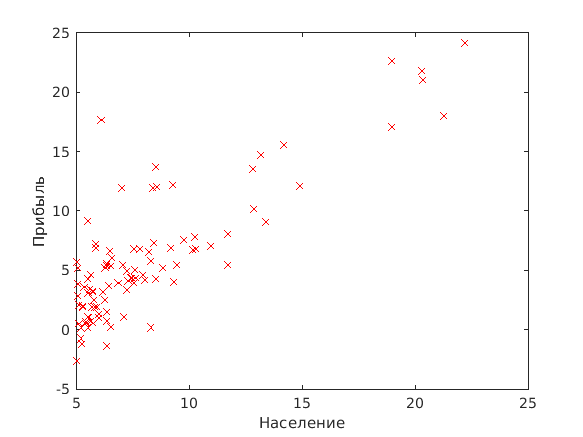

plot(X,y,'rx');
xlabel('Население');
ylabel('Прибыль');

3. Реализуйте функцию потерь J(θ) для набора данных **ex1data1.txt**.

4. Реализуйте функцию градиентного спуска для выбора параметров модели. Постройте полученную модель (функцию) совместно с графиком из пункта 2.

m = length(X);
X = [ones(m, 1), data(:,1)];
theta = zeros(2, 1);
iterations = 1500;
alpha = 0.01;
theta = gradientDescent(X, y, theta, alpha, iterations);
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2));

Theta computed from gradient descent:
-3.630291,
1.166362

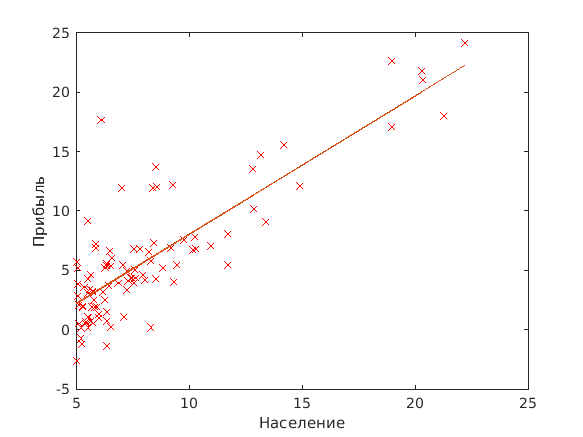

hold on;
plot(X(:,2), X*theta, '-');
hold off;

5. Постройте трехмерный график зависимости функции потерь от параметров модели (θ0 и θ1) как в виде поверхности, так и в виде изолиний (contour plot).

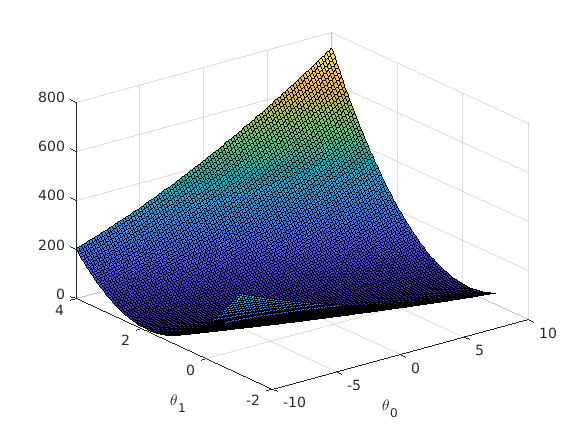

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end
% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

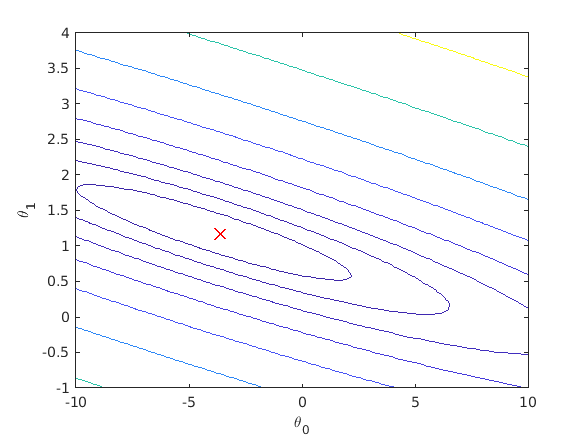


% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

6. Загрузите набор данных **ex1data2.txt** из текстового файла.

data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);

7. Произведите нормализацию признаков. Повлияло ли это на скорость сходимости градиентного спуска? Ответ дайте в виде графика.

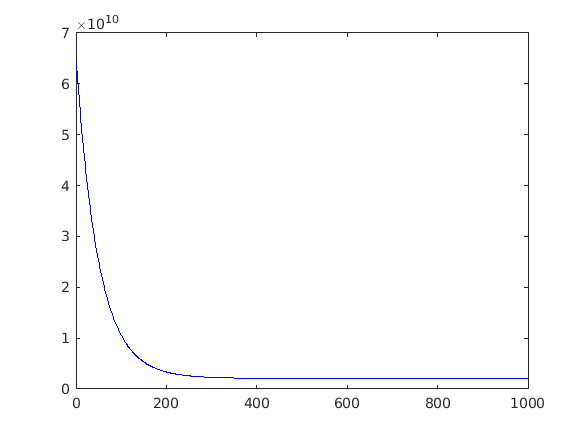

theta = 	1.0e+05 *

    3.4040
    1.0874
   -0.0587


[X, mu, sigma] = featureNormalize(X);
m = length(X);
X = [ones(m, 1) X];
theta = zeros(3, 1);
iterations = 1000;
alpha = 0.01;
[theta, J_history] = gradientDescentVectorized(X, y, theta, alpha, iterations);
plot(1:1000, J_history(1:1000), 'b');theta

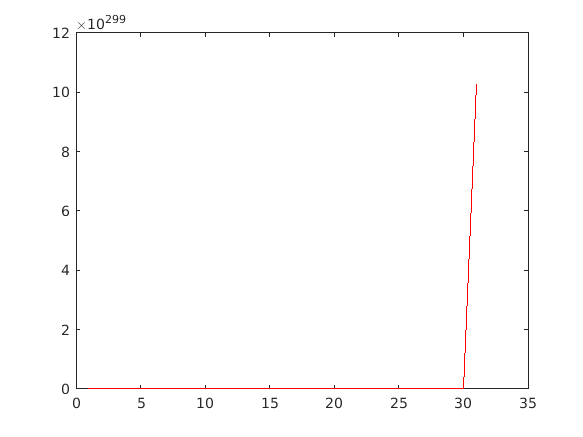

iterations = 200;
X = data(:, 1:2);
y = data(:, 3);
m = length(X);
X = [ones(m, 1) X];
theta = zeros(3, 1);
alpha = 0.01;
[theta, J_history2] = gradientDescent(X, y, theta, alpha, iterations);
plot(1:iterations, J_history2(1:iterations), 'r');

theta

theta =    NaN
   NaN
   NaN


8. Реализуйте функции потерь J(θ) и градиентного спуска для случая многомерной линейной регрессии с использованием векторизации.

9. Покажите, что векторизация дает прирост производительности.

data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
[X, mu, sigma] = featureNormalize(X);
m = length(X);
X = [ones(m, 1) X];
theta = zeros(3, 1);
iterations = 10000;
alpha = 0.01;
tic
gradientDescent(X, y, theta, alpha, iterations);
timeElapsedNonVectorized = toc

timeElapsedNonVectorized = 0.2906

theta = 	1.0e+05 *

    3.4041
    1.0945
   -0.0658


tic
gradientDescentVectorized(X, y, theta, alpha, iterations);
timeElapsedVectorized = toc

timeElapsedVectorized = 0.0837

10. Попробуйте изменить параметр ɑ (коэффициент обучения). Как при этом изменяется график функции потерь в зависимости от числа итераций градиентного спуск? Результат изобразите в качестве графика.

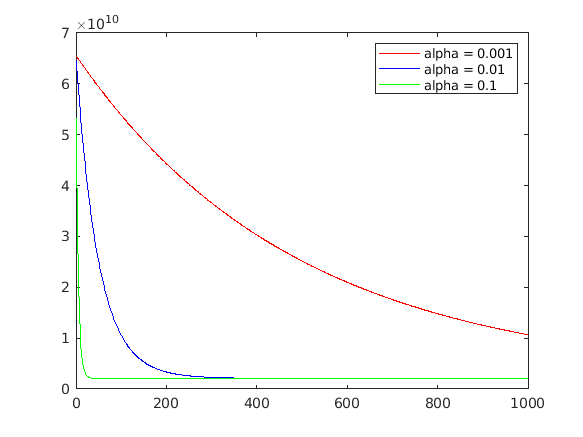

iterations = 1000;
theta = zeros(3, 1);
alpha = 0.001;
[theta, J_history2] = gradientDescentVectorized(X, y, theta, alpha, iterations);
plot(1:iterations, J_history2(1:iterations), 'r', 'DisplayName','alpha = 0.001');
hold on
theta = zeros(3, 1);
alpha = 0.01;
[theta, J_history2] = gradientDescentVectorized(X, y, theta, alpha, iterations);
plot(1:iterations, J_history2(1:iterations), 'b', 'DisplayName','alpha = 0.01');
theta = zeros(3, 1);
alpha = 0.1;
[theta, J_history2] = gradientDescentVectorized(X, y, theta, alpha, iterations);
plot(1:iterations, J_history2(1:iterations), 'g', 'DisplayName','alpha = 0.1');
legend
hold off

11. Постройте модель, используя аналитическое решение, которое может быть получено методом наименьших квадратов. Сравните результаты данной модели с моделью, полученной с помощью градиентного спуска.

theta = zeros(3, 1);
alpha = 0.10;
tic
[theta, J_history2] = gradientDescentVectorized(X, y, theta, alpha, iterations);
timeElapsedVectorized = toc

timeElapsedVectorized = 0.0046

theta

theta = 	1.0e+05 *

    3.4041
    1.0945
   -0.0658


theta = zeros(3, 1);
tic
theta = leastSquares(X, y);
timeElapsedVectorized = toc

timeElapsedVectorized = 0.0032

theta

theta = 	1.0e+05 *

    3.4041
    1.0945
   -0.0658
